# Expand Example 2.8:

This live script is for use with the textbook

*Continuous-Time Signals and Systems: A MATLAB Integrated Approach*

by Oktay Alkin, CRC Press, 2025.

In Example 2.8 we have found the response of the RC circuit shown below with element values R=1 $\Omega$ and $C=1/4$ F  to a unit step input signal $x(t)=u(t)$. The initial value of the output signal was assumed to be zero. Here we will solve the problem without assuming that the circuit is initially relaxed.  Instead, we will let $y(t_{0})=A$ at time instant $t_{0}\le 0$.

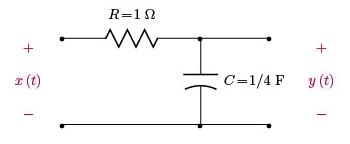

The differential equation for the circuit is

        $\frac{dy(t)}{dt}+\frac{1}{RC}\,y(t) = \frac{1}{RC}\,x(t)$                                                        (2.11)

Let $\alpha=\frac{1}{RC}$, so that we can write

        
$$\frac{dy(t)}{dt}+\alpha\,y(t) = \alpha\,x(t)$$


which can be solved as

        $y(t)=e^{-\alpha(t-t_{0})}\,y(t_{0})+\int_{t_{0}}^{t}e^{-\alpha(t-\tau)}\,\alpha\,x(\tau)\,d\tau$                                (2.49)

With $x(t)=u(t)$ and $y(t_{0})=A$, the solution becomes

        
$$y(t) = e^{-\alpha(t-t_{0})}\,A+(1-e^{-\alpha\,t})\,u(t)$$


R = 1; % Resistance
C = 0.25; % Capacitance
alpha = 1/(R*C);

t0 = -0.5; % Initial time
A = 1; % Initial value

Compute and graph the output signal $y(t)$ in the time interval $t_{0}<t<2$ s.

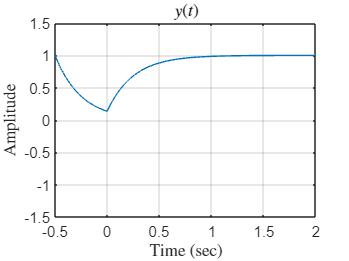

t = [t0:0.01:2];
y = exp(-alpha*(t-t0))*A+(1-exp(-alpha*t)).*(t>=0);
plot(t,y); grid;
axis([t0,2,-1.5,1.5]);
set(0,'defaultTextInterpreter','latex');
xlabel('Time (sec)');
ylabel('Amplitude');
title('$y(t)$');

set(0,'defaultTextInterpreter','tex');